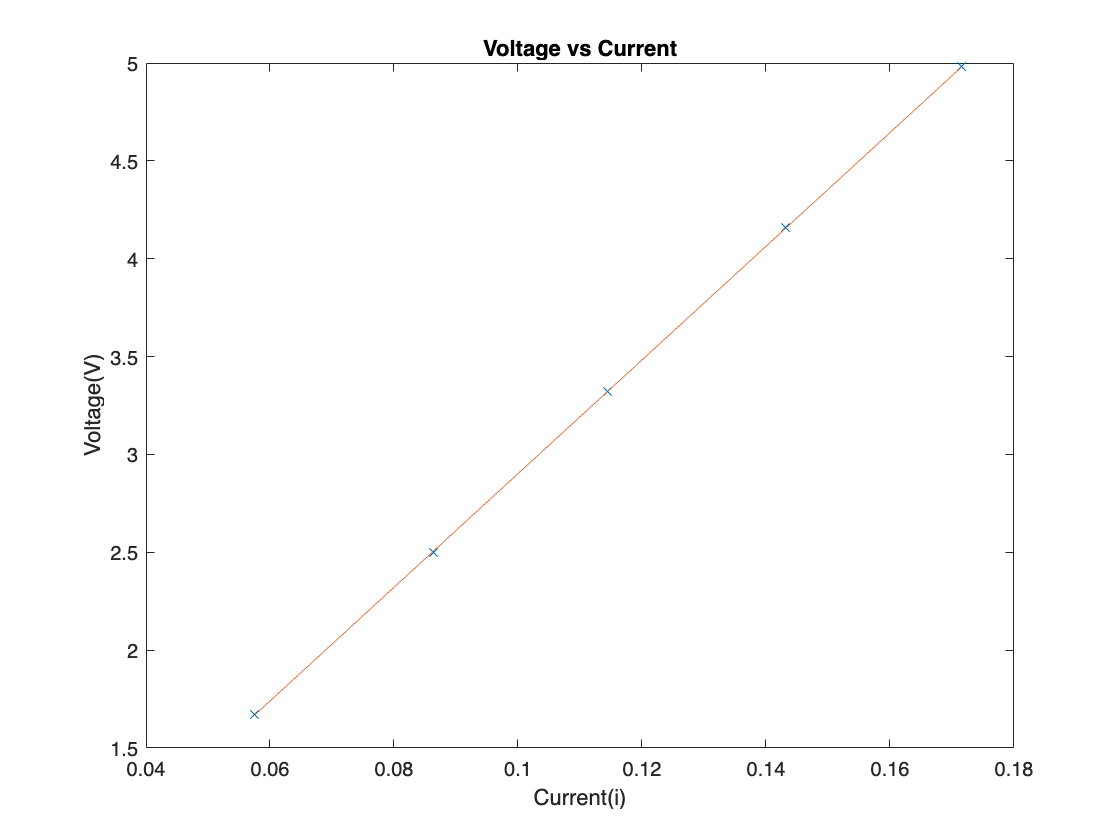

%Resistance R1
V = [1.67 2.50 3.32 4.16 4.98];
I = [57.5 86.3 114.4 143.2 171.6]/1000;

R1 = (V./I);
plot(I,V,"x");hold on;

xlabel("Current(i)");
ylabel("Voltage(V)");
title("Voltage vs Current");
stdDiv = std(R1);
p = polyfit(I,V,1);
R1_Slope = p(1);

%Error Analysis Code
n = length(I);
epsilon = sqrt(sum((V-p(1)*I - p(2)).^2)/(n-2));
delta = n*sum(I.^2) - (sum(I))^2;
sigmaA = sqrt(n*epsilon^2/delta);
sigmaB = sqrt(epsilon^2*sum(I.^2)/delta);
hold on;
plot(I,p(1)*I+p(2),'-');
hold off;

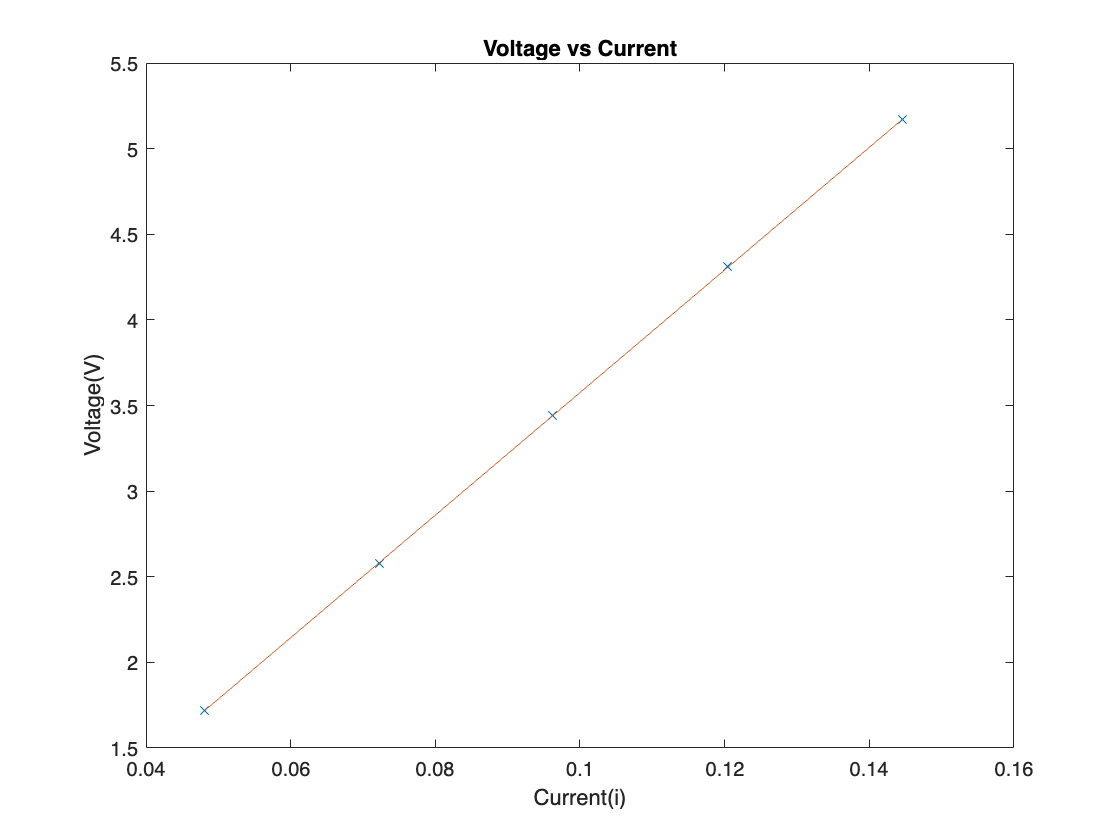

% Resistance R2
V2 = [1.72 2.58 3.44 4.31 5.17];
I2 = [48.1 72.3 96.2 120.4 144.6]/1000;

R2 = (V2./I2);
plot(I2,V2,"x");hold on;

xlabel("Current(i)");
ylabel("Voltage(V)");
title("Voltage vs Current");
stdDiv2 = std(R2);
p2 = polyfit(I2,V2,1);
R2_Slope = p2(1);

%Error Analysis Code
n2 = length(I2);
epsilon2 = sqrt(sum((V2-p2(1)*I2 - p2(2)).^2)/(n2-2));
delta2 = n2*sum(I2.^2) - (sum(I2))^2;
sigmaA2 = sqrt(n2*epsilon2^2/delta2);
sigmaB2 = sqrt(epsilon2^2*sum(I2.^2)/delta2);
hold on;
plot(I2,p2(1)*I2+p2(2),'-');
hold off;

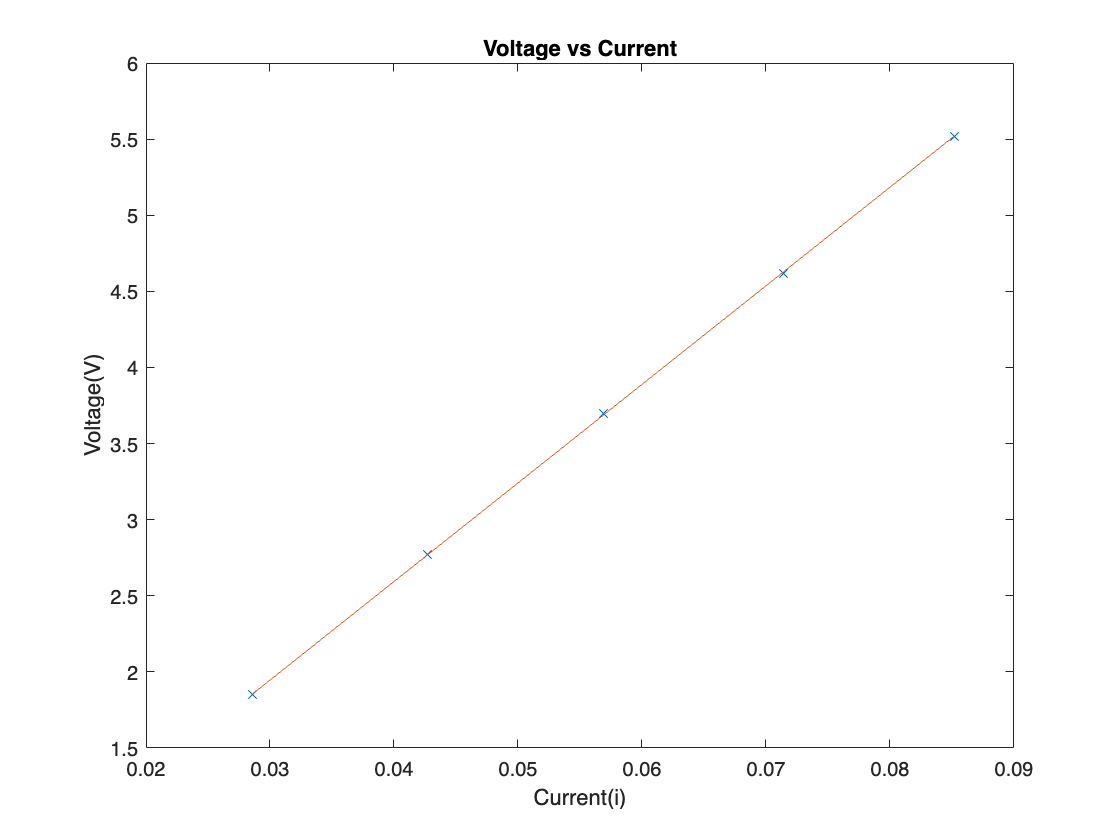


%Series Voltage vs. Current for R1 and R2

V3 = [1.85 2.77 3.70 4.62 5.52];
I3 = [28.6 42.7 56.9 71.4 85.2]/1000;

R3 = (V3./I3);
plot(I3,V3,"x");hold on;

xlabel("Current(i)");
ylabel("Voltage(V)");
title("Voltage vs Current");
stdDiv3 = std(R3);
p3 = polyfit(I3,V3,1);
R3_Slope = p3(1);

%Error Analysis Code
n3 = length(I3);
epsilon3 = sqrt(sum((V3-p3(1)*I3 - p3(2)).^2)/(n3-2));
delta3 = n3*sum(I3.^2) - (sum(I3))^2;
sigmaA3 = sqrt(n3*epsilon3^2/delta3);
sigmaB2 = sqrt(epsilon3^2*sum(I3.^2)/delta3);
hold on;
plot(I3,p3(1)*I3+p3(2),'-');
hold off;


%Parallel Voltage vs. Current for R1 and R2

V4 = [1.48 2.23 2.95 3.70 4.41];
I4 = [92.6 139.0 184.4 231 277]/1000;
R4 = mean(V4./I4);